## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)**** definida abaixo****.*

**b) **Listen the sound with f1 = 100, f2 = 2000 and fs = 4000 Hz.

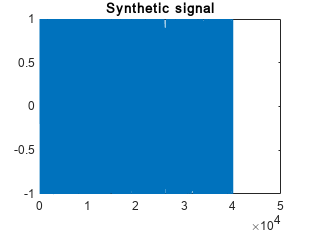

sound = chirpTone(10,100,2000,4000);

soundsc(sound);

**c) **Save the sound vector in an audio file to be read in normal audio players

fs = 4000;
audiowrite('synthetic.wav',sound,fs);

# **2) Real data**

**a) **Audio (1D)

**i) **Read the audio file ”Let It Be.mp3”.

let = audioread("Let It Be.mp3")

let =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


**b) **Compute the length of the file in seconds. Explain the approach you used. 

%informação acerca do ficheiro de áudio
audioinfo("Let It Be.mp3")

ans = struct with fields:
             Filename: 'C:\Users\mpatr\OneDrive - Universidade de Lisboa\FBIB\Lab1\Let It Be.mp3'
    CompressionMethod: 'MP3'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 10721662
             Duration: 243.1216
                Title: []
              Comment: []
               Artist: []
              BitRate: 192


%retirar a sample rate
SRate = audioinfo("Let It Be.mp3").SampleRate;
%determinar o número de samples
SNumber = size(let,1); % SNumber = audioinfo("Let It Be.mp3").TotalSamples
%a duração do ficheiro é igual ao número de samples sobre a sample rate
SLength = SNumber/SRate

SLength = 243.1097

**c) **Reproduce the music backwards.

%letR = let[]

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)*

function [x] = chirpTone(T,f1,f2,fs)
    stepT = 1/fs; %time step for time array
    time = 0:stepT:T; %time array
    %instead of a cosine, we introduce the phase -pi/2 for a sine
    x = chirp(time, f1, T, f2,"linear",-pi/2);
    plot (x);
    title("Synthetic signal");
end